# ACC Setup

## Convex Polyhedra $$\mathcal{U},\mathcal{Z}$, $\mathcal{C}$$

    clear;
    % Parameters
        [tau,um,vlm,M,g]=deal(1.7,0.4,16,1650,9.81);
    % Modeling
        [Ac,bc]=deal([1 -1.8],0);
    %Dimensions
        [nx,nz,nu]=deal(2,1,1);
 
        [Pu,Px,Pz]=deal(Polyhedron([-1;1],[um*M*g;um*M*g]),Polyhedron(-Ac,-bc),Polyhedron([-1;1],[-vlm;vlm+15]));

## Sample $\(U_0, X_0, Z_0,X_1\)$

(1) Collect data to form $\(U_0, X_0, Z_0,X_1\)$.

        %Sampling
            [t,T]=deal(10,0.1); % Data length and sample interval
        %Sample a group of data per Td interval
            [nCount,Td,xRange,uRange,zRange]=deal(t*100,4,[0 100;10 30],[-1,1]*um*M*g,[vlm,vlm+15]);
            
        sim("ACC_Sample.slx");
        [U0,X0,X1,Z0]=deal(ans.U0(2:Td:nCount*Td,:)',ans.X(2:Td:nCount*Td,:)',ans.X(3:Td:end,:)',ans.Z0(2:Td:nCount*Td,:)');

(2) Estimate  $\alpha,\Omega$

    %D0：Error Matrix
        Phi=sdpvar(nx,nx+nu+nz+1,'full');
        obj=norm(X1-Phi*[U0;X0;Z0;ones(1,nCount)],'fro');%F-norm
        options=sdpsettings('solver','mosek','verbose',0);
        sol=optimize([],obj,options);
        sol.info

ans = 'Successfully solved (MOSEK-CONE)'


        D0=value(X1-Phi*[U0;X0;Z0;ones(1,nCount)]);
    %Estimate alpha
        alpha=-inf; for i=1:nCount,alpha=max(alpha,2*norm(D0(:,i),'fro')/norm(X1(:,i),'fro'));end
    %U0,X0,X1,Omega
        %Select partial Datas
            random_numbers=randperm(nCount,t);
            [U0,X0,X1,Z0]=deal(U0(:,random_numbers),X0(:,random_numbers),X1(:,random_numbers),Z0(:,random_numbers));
        %Calculate Omega
            Omega=alpha*norm(X1,'fro');

(3) Full-row Rank Condition

    if rank([U0;X0;Z0;ones(1,t)])~=nx+nu+nz+1||rank(X1)~=nx, error('Failed to satisfy Full-row Rank Condition!'); end

### Construct robust $\mathcal{X}
$

%Recursive feasible without uncertainty
    [~,XSet]=Algorithm2ConstructRecursiveFeasibleSet_VRep(U0,X0,Z0,X1,Pu,Px,Pz)

Iteration:1
Iteration:2
Iteration:3
Iteration:4
Iteration:5
Iteration:6
Iteration:7
Iteration:8
Iteration:9
Iteration:10
Iteration:11
Iteration:12
Iteration:13
Iteration:14
Iteration:15
Iteration:16
Iteration:17
Iteration:18
Iteration:19
Iteration:20
Iteration:21
Iteration:22
Iteration:23
Iteration:24
Iteration:25
Iteration:26
Iteration:27
Iteration:28
Iteration:29
Iteration:30
Iteration:31
Iteration:32
Iteration:33
Iteration:34
Iteration:35
Iteration:36
Iteration:37
Iteration:38
Iteration:39
Iteration:40
Iteration:41
Iteration:42
Iteration:43
Iteration:44
Iteration:45
Iteration:46
Iteration:47
Iteration:48
Iteration:49
Iteration:50
Polyhedron in R^2 with representations:
    H-rep               : Unknown (call computeHRep() to compute)
    V-rep (irredundant) : Vertices  48 | Rays   2
Functions : none
Array of 50 polyhedra.


% Manual construction
    [x1,x2]=deal([60;25],[40;20]);
    Xf=Polyhedron([Px.A;[0 1;[x2(2)-x1(2) x1(1)-x2(1)]]],[Px.b;25;x1(1)*x2(2)-x1(2)*x2(1)]);

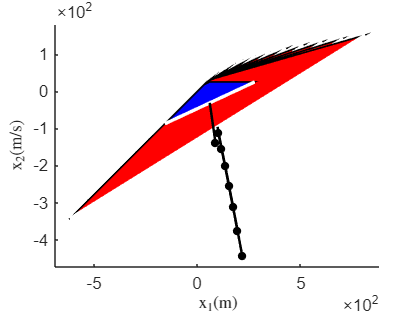

    run("ACC1_Draw.mlx");

    
    % Verification
        Theorem4_RecursiveRobustlyFeasible(U0,X0,Z0,X1,Pu,Xf,Pz,Omega);

ans = 'vgxz1:Successfully solved (MOSEK-SDP)'

ans = 'vgxz2:Successfully solved (MOSEK-SDP)'

ans = 'vgxz3:Successfully solved (MOSEK-SDP)'

ans = 'vgxz4:Successfully solved (MOSEK-SDP)'

ans = 'rgxz1:Successfully solved (MOSEK-SDP)'

ans = 'rgxz2:Successfully solved (MOSEK-SDP)'

#    Simulation

 % Define initial parameters
    [x0, rk] = deal([81; 17], 25);  
    Params0 = {U0, X0, Z0, X1, Xf, Pu, Px, Omega, T, [0 1], 0.2, 0.2, 5, 1e3, 1e3, 5e4};
    Params1 = {U0, X0, Z0, X1, Xf, Pu, Px, Omega, T, [0 1], 0.2, 0.2, 1, 1e3, 1e3, 5e4};
    
    % Flag variables
    Flag = {[0 0 0], [0 1 0], [0 1 1], [1 0 1], [1 1 0], [1 1 1]};
    
    % Define the Simulink model name
    modelName = 'ACC_QP';
    
    % Load the model
    load_system(modelName);
    
    % Preallocate SimulationInput object array
    simInputs(7) = Simulink.SimulationInput(modelName);
    
    % Generate Simulink.SimulationInput objects
    for i = 1:7
        if i == 7
            Params = [Params1, Flag{4}]; % The 7th experiment uses Params1
        else
            Params = [Params0, Flag{i}]; 
        end
        % Create Simulink.SimulationInput object and set parameters
        simInputs(i) = Simulink.SimulationInput(modelName)...
        .setVariable('Params', Params)... 
        .setVariable('x0', x0)... 
        .setVariable('rk', rk)... 
        .setVariable('T', T)... 
        .setVariable('M', M);
    end
    
    % Run simulations in parallel
    tic
        outANS = parsim(simInputs, 'ShowProgress', 'on'); 

[03-Mar-2025 18:58:27] 正在检查并行池的可用性...
[03-Mar-2025 18:58:27] 正在并行工作进程上启动 Simulink...
[03-Mar-2025 18:58:27] 正在并行编译模型引用...
[03-Mar-2025 18:58:27] 正在并行工作进程上配置仿真缓存文件夹...
[03-Mar-2025 18:58:27] 正在并行工作进程上加载模型...
[03-Mar-2025 18:58:28] 正在运行仿真...
[03-Mar-2025 19:59:22] 已完成 1 次仿真运行，共 7 次
[03-Mar-2025 19:59:22] 从并行工作进程接收的运行 1 的仿真输出(大小: 351.36 KB)。
[03-Mar-2025 20:01:59] 已完成 2 次仿真运行，共 7 次
[03-Mar-2025 20:01:59] 从并行工作进程接收的运行 2 的仿真输出(大小: 351.49 KB)。
[03-Mar-2025 20:07:53] 已完成 3 次仿真运行，共 7 次
[03-Mar-2025 20:07:53] 从并行工作进程接收的运行 3 的仿真输出(大小: 351.52 KB)。
[03-Mar-2025 20:07:53] 已完成 4 次仿真运行，共 7 次
[03-Mar-2025 20:07:53] 从并行工作进程接收的运行 4 的仿真输出(大小: 351.36 KB)。
[03-Mar-2025 20:07:53] 已完成 5 次仿真运行，共 7 次
[03-Mar-2025 20:07:53] 从并行工作进程接收的运行 5 的仿真输出(大小: 351.52 KB)。
[03-Mar-2025 20:08:16] 已完成 6 次仿真运行，共 7 次
[03-Mar-2025 20:08:16] 从并行工作进程接收的运行 6 的仿真输出(大小: 351.52 KB)。
[03-Mar-2025 20:08:16] 已完成 7 次仿真运行，共 7 次
[03-Mar-2025 20:08:16] 从并行工作进程接收的运行 7 的仿真输出(大小: 351.49 KB)。
[03-Mar-2025 20:08:16] 正在清理并行工作进程...


    toc

历时 4191.930328 秒。


# *Save all datas *

    save File

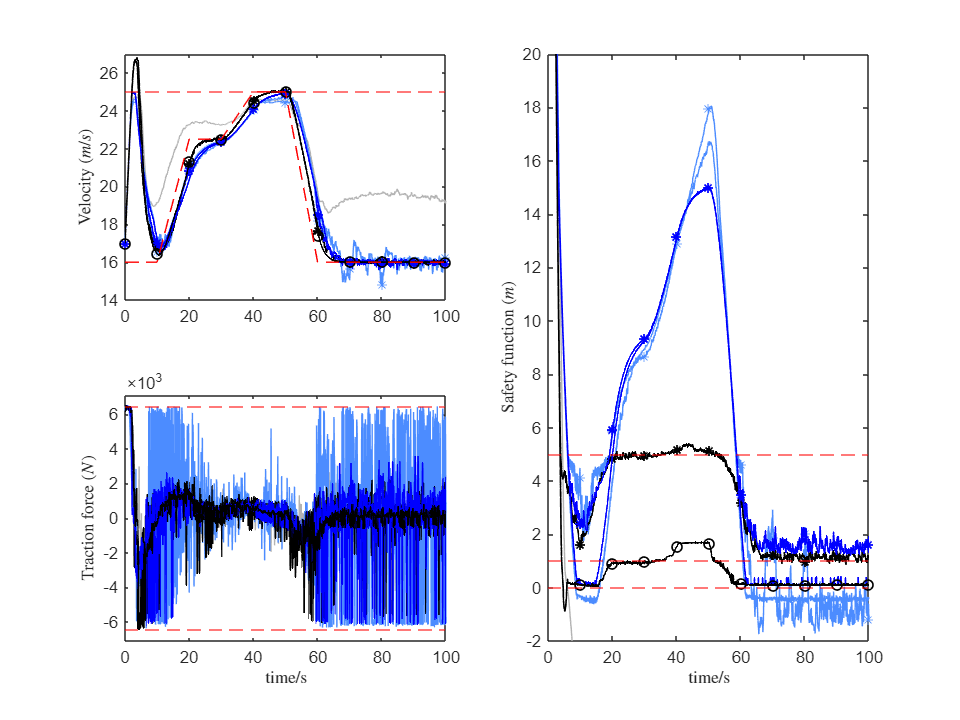

    run('ACC2_Draw.mlx')